clear
close all
clc

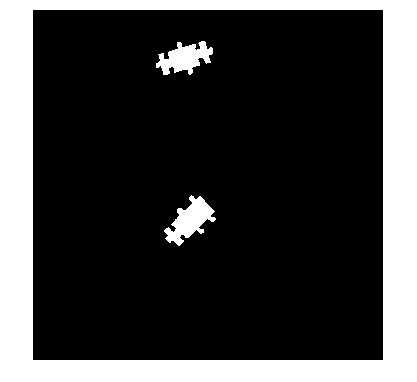

puzzleImage = imread("../../data/Data/MathWorks Images/MathWorks Puzzle/Puzzle_34.jpg");
puzzleMask = mySegmentPuzzle34(puzzleImage);

threePieceMask = bwpropfilt(puzzleMask,"Area",[20000 25000]);
threePieceProperties = regionprops('table',threePieceMask,["Area","Eccentricity"]);

threePieceLinearMask = bwpropfilt(threePieceMask,"Eccentricity",[0.8 1]);
threePieceLinearBoxes = regionprops('table',threePieceLinearMask,['BoundingBox']);
imshow(threePieceLinearMask)

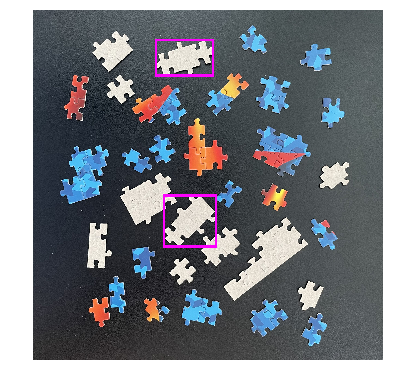


puzzleImageBoxed = insertShape(puzzleImage, "rectangle", threePieceLinearBoxes.BoundingBox,"Color","magenta","LineWidth",10);
imshow(puzzleImageBoxed)

function [BW,maskedImage] = mySegmentPuzzle34(X)
%segmentImage イメージの領域分割アプリから自動生成されたコードを使用してイメージをセグメント化
%  [BW,MASKEDIMAGE] = segmentImage(X) イメージの領域分割アプリから自動生成されたコードを使用してイメージ X
%  をセグメント化します。最終セグメンテーションは BW で返され、マスク イメージは MASKEDIMAGE で返されます。

% Auto-generated by imageSegmenter app on 14-Feb-2023
%----------------------------------------------------
HSV = rgb2hsv(X);
HSV(~repmat(HSV(:,:,3)>0.5, [1,1,3])) = 0;
X = hsv2rgb(HSV);
X = im2gray(X);

% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% イメージのしきい値処理 - 適応しきい値
BW = imbinarize(im2gray(X), 'adaptive', 'Sensitivity', 1.000000, 'ForegroundPolarity', 'bright');

% 穴の塗りつぶし
BW = imfill(BW, 'holes');

% default によるマスクのオープン
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = X;
end